# Integração Numérica - Exercícios

**Questão1) ** Aplique a Regra de Simpson, com $m=12$, para determinar o valor de $V$.


$$\displaystyle V = \pi\int_{0}^{4}\left(x\sqrt[3]{x+4} \right)^{2} \ dx$$


clear
a = 0;
b = 4;
m = 12; %subdivisões
h = (b-a)/m;
s1 = 0;
s2 = 0;
x = 0:h:b;
for i = 1:(m/2)
    s1 = s1 + fun(a+(2*i-1)*h); %soma os valores da função para os pontos intermediários de indíces ímpares
end
for i = 1:(m/2)-1
    s2 = s2 + fun(a+(2*i)*h); %soma os valores da função para os pontos intermediários de indíces pares
end
ATSR = (h/3)*(fun(a) + 4*s1 + 2*s2 + fun(b));
V = pi*ATSR;
fprintf("%f", V)

244.897152

usando quadratura gaussiana G(1)

clear
a = 0;
b = 4;
x0 = ((a+b)/2) - (b-a)/(2*sqrt(3));
x1 = ((a+b)/2) + (b-a)/(2*sqrt(3));

G1 = ((b-a)/2) * (fun(x0) + fun(x1));

V = pi*G1

V =      2.450347336222254e+02


**Questão2) ** Um corpo assimila um comprimido para resfriado com efeito em 12 horas, a uma taxa cujo modelo é


$$\frac{dC}{dt}=8 - \ln{(t^{2}-2t+4)}, \ 0 \leq t \leq 12$$


onde $\frac{dC}{dt}$ é dada em gramas por hora e $t$ é o tempo (em horas). Determine a quantidade total de remédio absorvida pelo corpo durante as 12 horas.

Supondo que desejássemos determinar a quantidade total de medicamento de tal forma que o erro fosse inferior a 0,001 teríamos que utilizar quantas subdivisões $m$ do intervalo [0,12]?

% Cálculo da quantidade total de remédio (Regra do Trapézio com m = 310)
clear
a = 0;
b = 12;
m = 310; % Subdivisões para erro < 0.001
h = (b - a) / m;
x = a:h:b;

% Soma dos termos intermediários
soma = 0;
for i = 2:m
    soma = soma + funt(x(i));
end

% Aproximação da integral
integral = (h/2) * (funt(a) + 2*soma + funt(b));
fprintf('Quantidade total de remédio: %.4f gramas\n', integral);

Quantidade total de remédio: 58.8763 gramas



% Verificação do erro
fprintf('Subdivisões necessárias (m): %d\n', m);

Subdivisões necessárias (m): 310


**Questão 3) ** Calcule o trabalho realizado por um gás sendo aquecido segundo a tabela: Sabe-se que $\displaystyle W=\int_{v_{i}}^{v_{f}}P \ dV$. Use $h=0.25$.

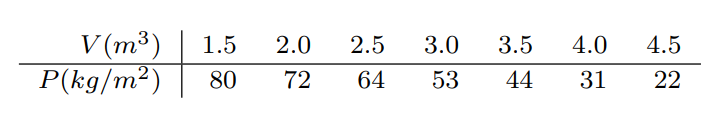

*Você terá que fazer interpolação para os pontos que não estão na tabela.

% Dados da tabela
V_conhecido = [1.5, 2.0, 2.5, 3.0, 3.5, 4.0, 4.5];
P_conhecido = [80, 72, 64, 53, 44, 31, 22];

% Gerar pontos V com h = 0.25
V = 1.5:0.25:4.5;

% Interpolação linear para obter P nos pontos V
P = interp1(V_conhecido, P_conhecido, V, 'linear');

% Cálculo da integral usando a Regra do Trapézio
h = 0.25;
n = length(V);
integral = (h/2) * (P(1) + 2*sum(P(2:end-1)) + P(end));

% Exibição do resultado
fprintf('Trabalho realizado W = %.4f kg.m²\n', integral);

Trabalho realizado W = 157.5000 kg.m²


questão 4) Calcular usando quadratura gaussiana com dois pontos o valor de $\displaystyle\int_{-2}^{2}e^{-\frac{x^{2}}{2}}dx$

clear
a = -2;
b = 2;
x0 = ((a+b)/2) - (b-a)/(2*sqrt(3));
x1 = ((a+b)/2) + (b-a)/(2*sqrt(3));

G1 = ((b-a)/2) * (f3(x0) + f3(x1))

G1 =    2.053668476130368


V = pi*G1

V =    6.451789797520108


function f = fun(x)
    f = (x*nthroot(x+4,3))^2;
end

function y = f3(x)
    y = exp((-x.^2)/2);
end

function y = funt(t)
    y = 8 - log(t.^2 - 2*t + 4);
end